# HW 1 solution

This is the solution for HW 1. Let's first set the random seed such that our results are replicable(same random numbers drawn)

rng('default');

Instructions are to use the dataset 'data1945_2015.xlsx' containing real price $$P_t$ and dividend $$D_t$ over years 1945 through 2015. We first compute and save two variables, continuously compounded returns(including dividends) $$r_t$, and log dividend-price ratio $$dp_t$ for the exercises below.


$$$r_t = log\big(\frac{P_t+D_t}{P_{t-1}}\big)$$
 
$$$dp_t = \log(D_t/P_t)$$


We first read data. I use 'xlsread' command in Matlab to read numerical values. Note that the the function gives 3 outputs so you need to make room for all three. I only need the first output so I do the following.

[num,~,data]=xlsread('data1945_2015.xlsx');

Now we can define variables accordingly. 

P_real = num(:,2);
D_real = num(:,3);
[K,~] = size(P_real); % this gets the length of the P_real vector.

We need to creating leading variable and lagging variable for our definitions. In order to create lead and lags, you must drop some data points such that the timing of our variables match our definition. So we do the following for price.

P_real_lead = P_real(2:K,1); % leading term
P_real_lag = P_real(1:K-1,1); % lagging term

We also need the leading term for dividend. 

D_real_lead = D_real(2:K,1);

Now we are ready to define continuously compounded returns(including dividends) and log dividend-price ratio.

ccr = log( (P_real_lead+D_real_lead)./P_real_lag );
dp = log(D_real./P_real);

## Q1

Here I provide a brief summary statistics for our variables.

## Part A

summary = [ccr dp(2:end)];
mean(summary,1)

ans =     0.0646   -3.4782


median(summary,1)

ans =     0.0983   -3.4558


std(summary,0,1)

ans =     0.1695    0.4411


min(summary,[],1)

ans =    -0.4559   -4.4777


max(summary,[],1)

ans =     0.4211   -2.6308


skewness(ccr)

ans = -0.8000

skewness(dp(2:end))

ans = -0.2782

## Part B

Now I draw the autocorrelation plots for the two variables. I use the `autocorr' Matlab function for both variables in order to get the pictures. Each point on the plot is the autocorrelation value corresponding to the number of lags indicated on the x-axis.

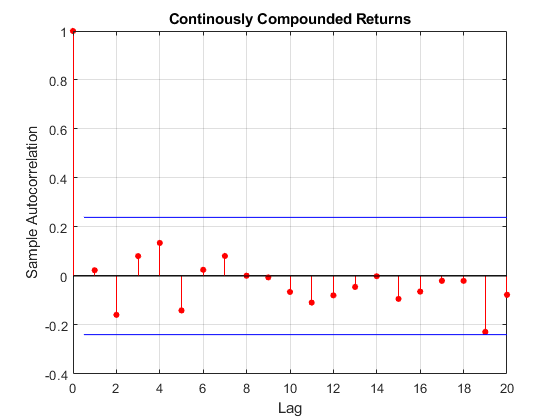

figure(1)
autocorr(ccr);
title('Continously Compounded Returns')

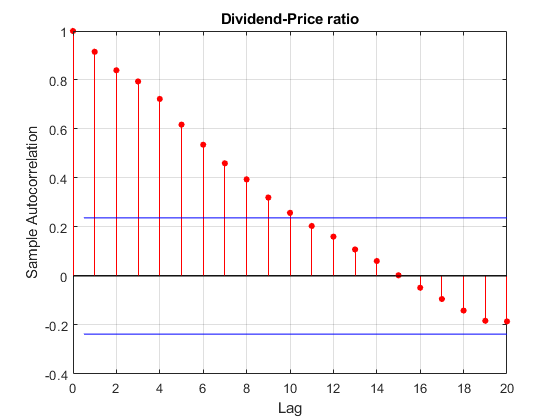

figure(2)
autocorr(dp);
title('Dividend-Price ratio')

As the plots show, autocorrelation at different lags for Continously Compounded Returns is relatively small, whereas for Dividend-Price ratio, the autocorrelation structure is very visible that diminishes as the lags increase.

## Part C

Estimate the AR(1) slope for two variables respectively. First I estimate the covariance matrix for $$r_t$ and $$r_{t-1}$. The off-diagonal terms are the covariance between them, or in this case, autocovariance at lag 1. We then divide it with variance of $$r_t$ to get the autocorrelation at lag 1. This value corresponds to y-axis value in the plot of `autocorr(dp)` at lag 1.

A = cov(ccr(2:end),ccr(1:end-1));
coef_1 = A(1,2)./var(ccr(1:end-1)); 
% We repeat the exercise for Dividend-Price ratio.
B = cov(dp(2:end),dp(1:end-1));
coef_2 = B(1,2)./var(dp(1:end-1));

## Part D

Now using the log dividend-price ratio as the predictor, I run a predictive regression of form $y_t = \alpha+dp_{t-1}\beta+\epsilon_t$ using least squares. Report the R-square, the slope estimate, t-statistic for the two-sided test of predictability, and its p-value. 

dp_pred = dp(1:K-1,1); % I lose the last observation to match the timing.
builtinResult = fitlm(dp_pred,ccr); % This is the built-in command for running regression on Matlab.

A little more involved way, but more detailed is the code below.

eta = ones(K-1,1);
X = [eta,dp_pred]; % The covariate matrix for our regression; it is lagging one period to ccr
beta = (X'*X)\(X'*ccr);
R_squared = 1-(ccr'*(eye(K-1)-X*inv(X'*X)*X')*ccr)/(ccr'*(eye(K-1)-eta*inv(eta'*eta)*eta')*ccr);
Adj_R_squared = 1-69/68*(ccr'*(eye(K-1)-X*inv(X'*X)*X')*ccr)/(ccr'*(eye(K-1)-eta*inv(eta'*eta)*eta')*ccr);

One last thing that we can do is to use LeSage's Toolbox to get our results. The `structure' variable 'res' contains all the things we wanted for this exercise.

res = ols(ccr,X);
tstat = res.tstat(2);

res.tstat(2) reads the 2nd t-statistic value which is the t-statistic for the slope coefficient. 

pv = 2*(1-normcdf(tstat)); % A two-sided test.

## Q2

We are now given an autoregressive model of order 1, AR(1), of a stationary scalar $$y_t$. The main purpose of this exercise is to give you chance to simulate data given model and compare the estimated autocovariances from simulated data with theoretical autocovariances coming from econometrics theory. *You should see they are pretty similar so the theory holds nicely in empirical applications***.** **Also as you have more sample size, they become more similar!**

## Part C

Let $$y_t = 0.8y_{t-1}+\epsilon_t, \epsilon_t\sim~N(0,1)$ be the data generating process(DGP). Simulate, estimate and plot the sample autocorrelation function for this AR(1) with simulated sample size of 100 and 1000 respectively. The plot should be with respect to the number of lags, and plot up to 30 lags.

Let's define the parameters required for our exercise

T_1 = 100;
T_2 = 1000;
slope = 0.8;

Simulate Data and plot the results. How does AR_gen.m look like? What is 500?

sim_1 = AR_one_gen(slope,500,T_1);
sim_2 = AR_one_gen(slope,500,T_2);

Calculate sample estimates of the autocorrelation function. How does acf_estimate.m look like? 

[~,acr_1] = acf_estimate(sim_1,30);
[~,acr_2] = acf_estimate(sim_2,30);

## Part D

Compare autocorrelation sample estimates to theoretical expressions. In theory the autocorrelation function of an AR(1) model is the slope value to the power of the number of lags in question.

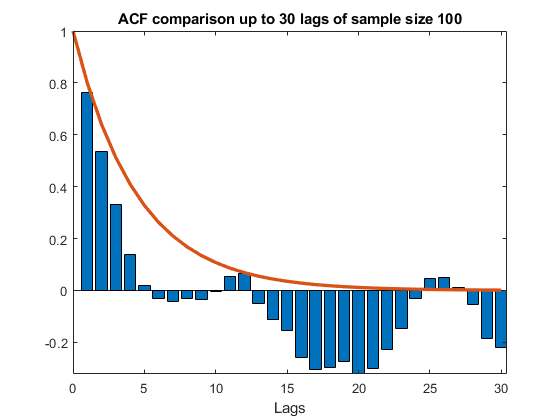

k = 0:30; % maximum lags I want to observe is 30;
acf = slope.^k; % the theoretical autocorrelation function at lag k

figure(5)
bar3 = bar(acr_1);
axis tight
hold on;
p = plot(k,acf);
p(1).LineWidth = 2.5;
title('ACF comparison up to 30 lags of sample size 100')
xlabel('Lags')
hold off;

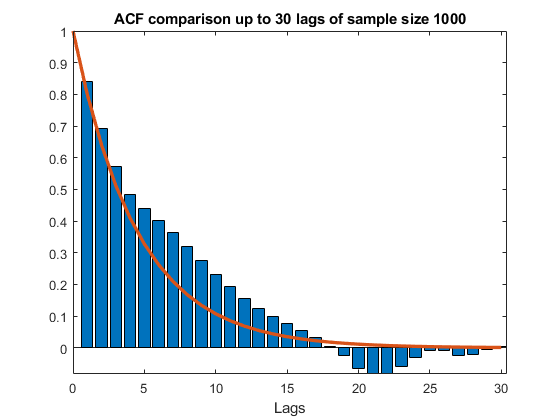


figure(6)
bar4 = bar(acr_2);
axis tight
hold on;
p = plot(k,acf);
p(1).LineWidth = 2.5;
title('ACF comparison up to 30 lags of sample size 1000')
xlabel('Lags')
hold off;